clear; clc;

function [rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points)
    % Function to compute E0(rho)
    G = @(z) (1/pi) * exp(-abs(z).^2);
    
    % Log initial inputs
    disp('--- Initial Inputs ---');
    disp(['X: ', mat2str(X)]);
    disp(['Q: ', mat2str(Q)]);
    disp(['Nodes: ', mat2str(nodes)]);
    disp(['Weights: ', mat2str(weights)]);
    disp(['SNR: ', num2str(SNR)]);
    disp(['Num Points: ', num2str(num_points)]);
    
    % Create complex quadrature nodes matrix
    disp('--- Creating Z Matrix ---');
    N = length(nodes);
    z_matrix = createComplexNodesMatrix(nodes);
    disp('Z_MATRIX:');
    disp(z_matrix);
    disp(['Size of Z_MATRIX: ', mat2str(size(z_matrix))]);
    
    % Create Pi matrix
    disp('--- Creating Pi Matrix ---');
    M = length(X);
    pi_matrix = createPiMatrix(M, N, weights);
    disp('PI_MATRIX:');
    disp(pi_matrix);
    disp(['Size of PI_MATRIX: ', mat2str(size(pi_matrix))]);
    
    % Create G matrix
    disp('--- Creating G Matrix ---');
    g1_matrix = createGMatrix(X, z_matrix, SNR, G);
    disp('G_MATRIX:');
    disp(g1_matrix);
    disp(['Size of G_MATRIX: ', mat2str(size(g1_matrix))]);
    
    % Compute rho values (always between 0 and 1)
    disp('--- Generating Rho Values ---');
    rho_values = linspace(0, 1, num_points);
    disp(['Rho Values: ', mat2str(rho_values)]);
    
    % Preallocate Eo_rho
    Eo_rho = zeros(size(rho_values));
    disp('--- Starting E0 Computation ---');
    
    % Compute E0(rho) for different rho values
    for idx = 1:length(rho_values)
        rho = rho_values(idx);

        % Compute intermediate terms
        g_powered = g1_matrix.^(1 / (1 + rho));
        qg_rho = Q * g_powered;
        qg_rho_t = qg_rho.^rho;        
        pi_g_rho = pi_matrix .* (g1_matrix.^(-rho / (1 + rho)));

        % Combine results
        component_second = Q * (pi_g_rho * qg_rho_t');
        
        % Final calculation for E_0(rho)
        Eo_rho(idx) = -log2((1 / pi) * component_second);
    end
    
    disp('--- Final Results ---');
    disp(['Eo_Rho: ', mat2str(Eo_rho)]);
end

function z_matrix = createComplexNodesMatrix(nodes)
    N = length(nodes);
    z_matrix = zeros(N, N);
    disp('--- Creating Complex Nodes Matrix ---');
    for i = 1:N
        for j = 1:N
            disp(['Node[i]: ', num2str(nodes(i)), ' | Node[j]: ', num2str(nodes(j))]);
            z_matrix(i,j) = nodes(i) + 1i*nodes(j);
        end
    end
end

function pi_matrix = createPiMatrix(M, N, weights)
    % Initialize matrix with zeros
    pi_matrix = zeros(M, N^2*M);
    
    % For each row
    for i = 1:M
        % For all combinations of weights
        idx = 1;
        for j = 1:N
            for k = 1:N
                % Calculate weight product
                pi_block = weights(j)*weights(k);
                % Calculate column position
                col = (i-1)*N^2 + idx;
                % Assign the weight product
                pi_matrix(i, col) = pi_block;
                idx = idx + 1;
            end
        end
    end
end

function g_matrix = createGMatrix(X, z_matrix, SNR, G)
    M = length(X);
    N = size(z_matrix, 1);
    g_matrix = zeros(M, N^2*M);
    
    for i = 1:M % Source symbols
        for j = 1:M % Received symbols
            for k = 1:N % First quadrature nodes
                for l = 1:N % Second quadrature nodes
                    % Compute column index
                    col_idx = (j-1)*N^2 + (k-1)*N + l;
                    
                    % Compute G values
                    g_matrix(i, col_idx) = G(z_matrix(k,l) + (sqrt(SNR)*X(i)) - (sqrt(SNR)*X(j)));
                end
            end
        end
    end
end

%M = 4;  % Constellation size
%amplitude = 5;
%X = linspace(-amplitude, amplitude, M);

M_const = 2;
X = zeros(1,M_const);
aux = -(M_const-1);
for i = 1:M_const
    X(i) = aux;
    aux = aux + 2;
end 

avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);
Q = ones(1, M_const) / M_const;
disp(X)

    -1     1



% Fixed parameters
SNR = 1;
num_points = 1000;

N = 2;  % Number of points
[nodes, weights] = GaussHermite_Locations_Weights(N);
disp(nodes)

  -0.707106781186548
   0.707106781186547



disp(weights)

   0.886226925452758
   0.886226925452758



% Compute E0(rho)
tic;
[rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points);

--- Initial Inputs ---
X: [-1 1]
Q: [0.5 0.5]
Nodes: [-0.707106781186548;0.707106781186547]
Weights: [0.886226925452758;0.886226925452758]
SNR: 1
Num Points: 1000
--- Creating Z Matrix ---
--- Creating Complex Nodes Matrix ---
Node[i]: -0.70711 | Node[j]: -0.70711
Node[i]: -0.70711 | Node[j]: 0.70711
Node[i]: 0.70711 | Node[j]: -0.70711
Node[i]: 0.70711 | Node[j]: 0.70711
Z_MATRIX:
 -0.707106781186548 - 0.707106781186548i -0.707106781186548 + 0.707106781186547i
  0.707106781186547 - 0.707106781186548i  0.707106781186547 + 0.707106781186547i

Size of Z_MATRIX: [2 2]
--- Creating Pi Matrix ---
PI_MATRIX:
   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449

Size of PI_MATRIX: [2 8]
--- Creating G Matrix ---
G_MATRIX:
   0.1

execution_time = toc;

fprintf('Execution time: %.6fs\n', execution_time);

Execution time: 0.026624s


disp(Eo_rho)

                   0   0.000805089312198   0.001609741599118   0.002413957289499   0.003217736810964   0.004021080590025   0.004823989052080   0.005626462621417   0.006428501721214   0.007230106773537   0.008031278199345   0.008832016418488   0.009632321849711   0.010432194910648   0.011231636017832   0.012030645586690   0.012829224031544   0.013627371765616   0.014425089201026   0.015222376748791   0.016019234818831   0.016815663819969   0.017611664159928   0.018407236245335   0.019202380481725   0.019997097273536   0.020791387024117   0.021585250135721   0.022378687009516   0.023171698045578   0.023964283642897   0.024756444199376   0.025548180111833   0.026339491776004   0.027130379586541   0.027920843937017   0.028710885219924   0.029500503826678   0.030289700147617   0.031078474572004   0.031866827488031   0.032654759282814   0.033442270342401   0.034229361051772   0.035016031794837   0.035802282954442   0.036588114912368   0.037373528049335   0.038158522744999   0.038943099377960

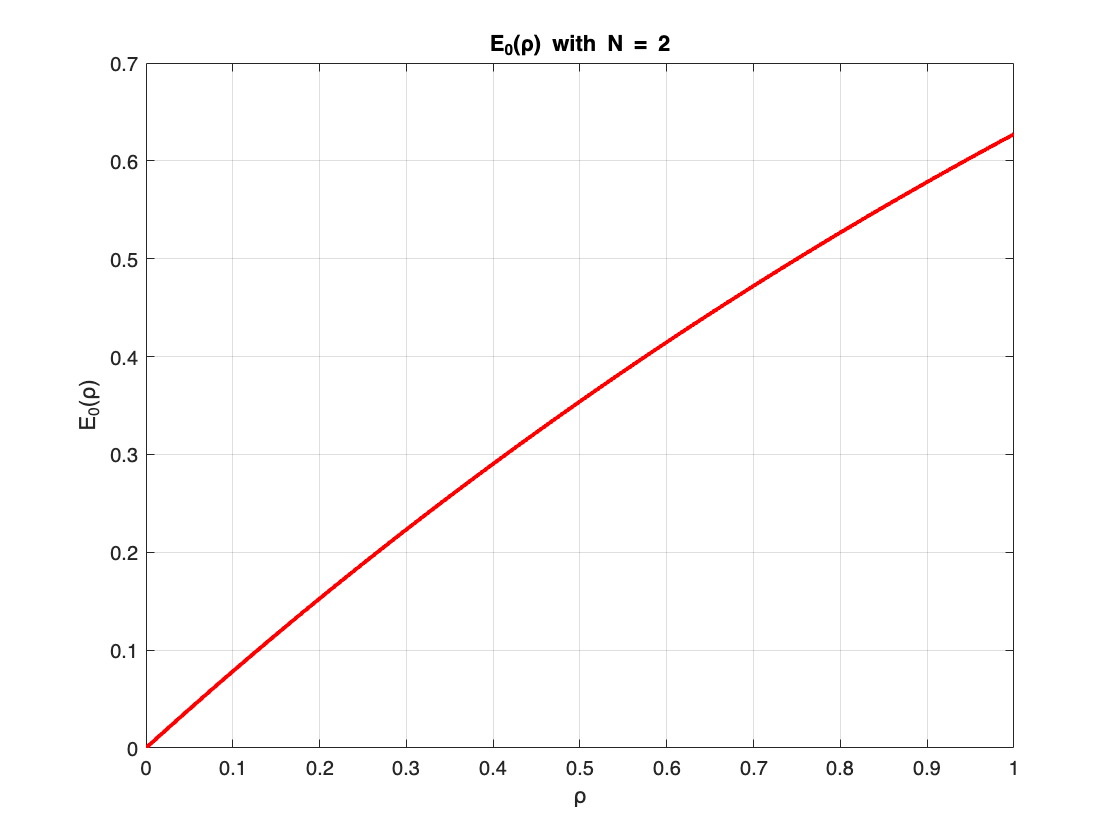

close all;
figure;
plot(rho_values, Eo_rho, 'linewidth', 2, 'color', 'r');
title(['E_0(ρ) with N = ', num2str(length(nodes))]);
xlabel('ρ');
ylabel('E_0(ρ)');
grid on;

--- Initial Inputs ---
X: [-1 1]
Q: [0.5 0.5]
Nodes: [-0.707106781186547 0.707106781186547]
Weights: [0.886226925452758 0.886226925452758]
SNR: 1
Num Points: 1000
--- Creating Z Matrix ---
--- Creating Complex Nodes Matrix ---
Node[i]: -0.70711 | Node[j]: -0.70711
Node[i]: -0.70711 | Node[j]: 0.70711
Node[i]: 0.70711 | Node[j]: -0.70711
Node[i]: 0.70711 | Node[j]: 0.70711
Z_MATRIX:
 -0.707106781186547 - 0.707106781186547i -0.707106781186547 + 0.707106781186547i
  0.707106781186547 - 0.707106781186547i  0.707106781186547 + 0.707106781186547i

Size of Z_MATRIX: [2 2]
--- Creating Pi Matrix ---
PI_MATRIX:
   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448

Size of PI_MATRIX: [2 8]
--- Creating G Matrix ---
G_MATRIX:
   0.1

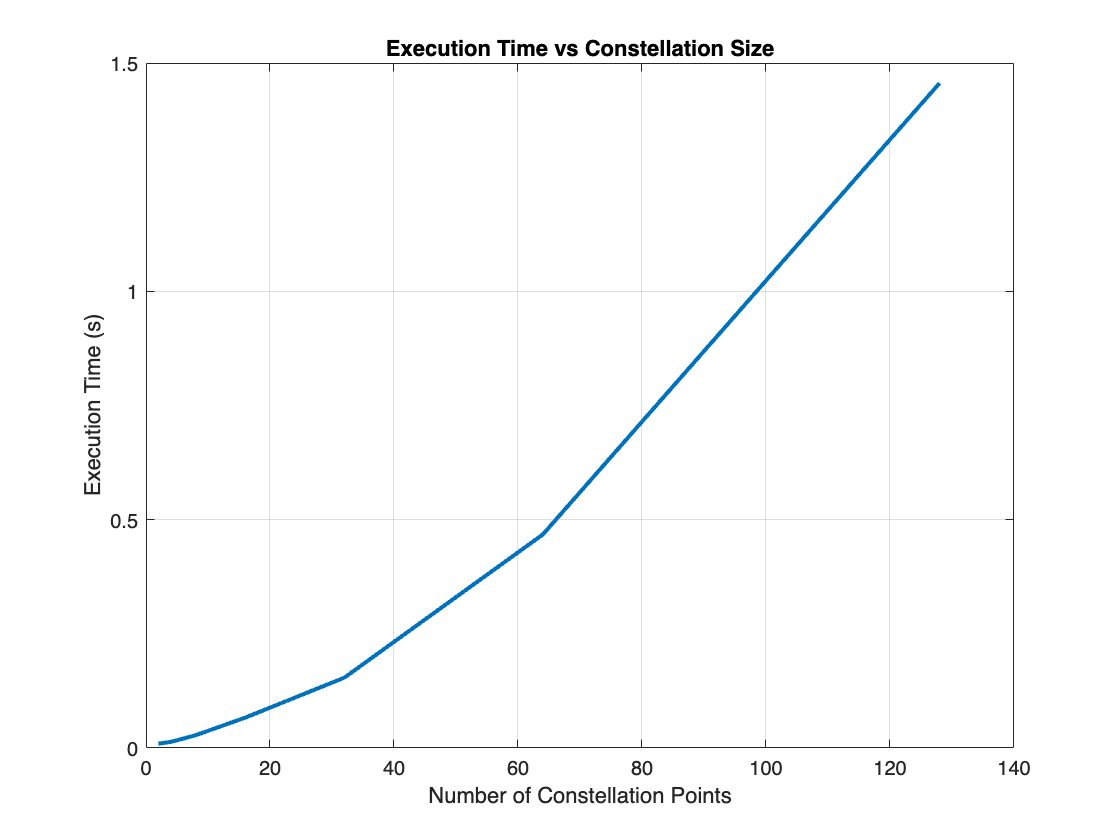

Size	Time
2 -> 0.009446 s
4 -> 0.013294 s
8 -> 0.027938 s
16 -> 0.066459 s
32 -> 0.154055 s
64 -> 0.467475 s
128 -> 1.455960 s


function runConstellationPerformance()    
    constellation_sizes = [2, 4, 8, 16, 32, 64, 128];
    
    execution_times = zeros(size(constellation_sizes));
    constellation_points = cell(size(constellation_sizes));
    
    SNR = 1;
    num_points = 1000;
    nodes = [-1/sqrt(2), 1/sqrt(2)];
    weights = [sqrt(pi)/2, sqrt(pi)/2];
    
    for idx = 1:length(constellation_sizes)
        % Current constellation size
        M = constellation_sizes(idx);
        
        % Generate and normalize constellation
        amplitude = 3;
        X = linspace(-amplitude, amplitude, M);
        avg_energy = mean(X.^2);
        X = X / sqrt(avg_energy);
        
        % Store constellation points
        constellation_points{idx} = X;
        
        % Equal probabilities
        Q = ones(1, M) / M;
        
        % Measure execution time
        tic;
        [~, ~] = computeEO(X, Q, nodes, weights, SNR, num_points);
        execution_times(idx) = toc;
    end
    
    figure;
    plot(constellation_sizes, execution_times, 'LineWidth',2);
    title('Execution Time vs Constellation Size');
    xlabel('Number of Constellation Points');
    ylabel('Execution Time (s)');
    grid on;
    
    fprintf('Size\tTime\n');
    for idx = 1:length(constellation_sizes)
        fprintf('%d -> %.6f s\n', constellation_sizes(idx), execution_times(idx));
    end
end

runConstellationPerformance();

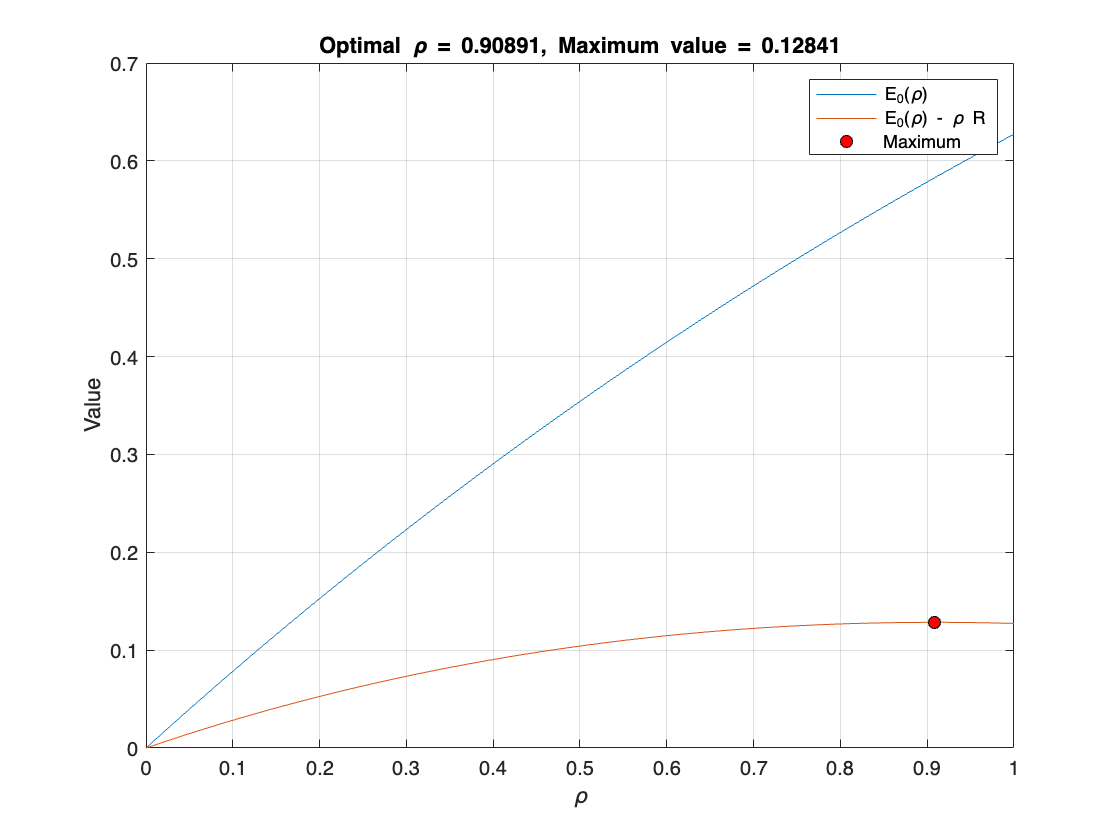

% Define R
R = 0.5;

% Calculate E0(ρ) - ρ·R
toOptimize = Eo_rho - R*rho_values;

% Find maximum and its index
[max_value, max_idx] = max(toOptimize);
optimal_rho = rho_values(max_idx);

% Plot
figure;
plot(rho_values, Eo_rho);
hold on;
plot(rho_values, toOptimize);
plot(optimal_rho, max_value, 'ko', 'MarkerFaceColor', 'r');
xlabel('\rho');
ylabel('Value');
legend('E_0(\rho)', 'E_0(\rho) - \rho R', 'Maximum');
title(['Optimal \rho = ', num2str(optimal_rho), ', Maximum value = ', num2str(max_value)]);
grid on;

function val = E0_of_rho(rho, Q, pi_mat, G)
    val = -log2( ...
       (1/pi) * Q' * ( pi_mat .* ( G.^(-rho/(1+rho)) ) ) * ( (Q'* (G.^(1/(1+rho)) ) )^rho )' ...
    );
end

pi_matrix = createPiMatrix(M_const, N, weights)

pi_matrix =    0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449


G = @(z) (1/pi) * exp(-abs(z).^2);
z_matrix = createComplexNodesMatrix(nodes);

--- Creating Complex Nodes Matrix ---
Node[i]: -0.70711 | Node[j]: -0.70711
Node[i]: -0.70711 | Node[j]: 0.70711
Node[i]: 0.70711 | Node[j]: -0.70711
Node[i]: 0.70711 | Node[j]: 0.70711


g_matrix = createGMatrix(X, z_matrix, SNR, G);

% Define R
R = 0.5;

cvx_begin

   variable rho(1)
   minimize(E0_of_rho(rho, Q, pi_matrix, g_matrix) - rho*R)

Error using  .*  (line 173)
Disciplined convex programming error:
    Cannot perform the operation: {real affine} ./ {real affine}

Error in  ./  (line 19)
z = times( x, y, './' );

Error in  *  (<a 

   subject to
       0 <= rho <= 1
cvx_end

figure;
plot(rho_values, Eo_rho);
hold on;
plot(rho_values, toOptimize);
plot(optimal_rho, max_value, 'ko', 'MarkerFaceColor', 'r');
xlabel('\rho');
ylabel('Value');
legend('E_0(\rho)', 'E_0(\rho) - \rho R', 'Maximum');
title(['Optimal \rho = ', num2str(optimal_rho), ', Maximum value = ', num2str(max_value)]);
grid on;